## BIV-Übung 1

Hadi Saleh 1822230

### 2 Farbbilder

a)

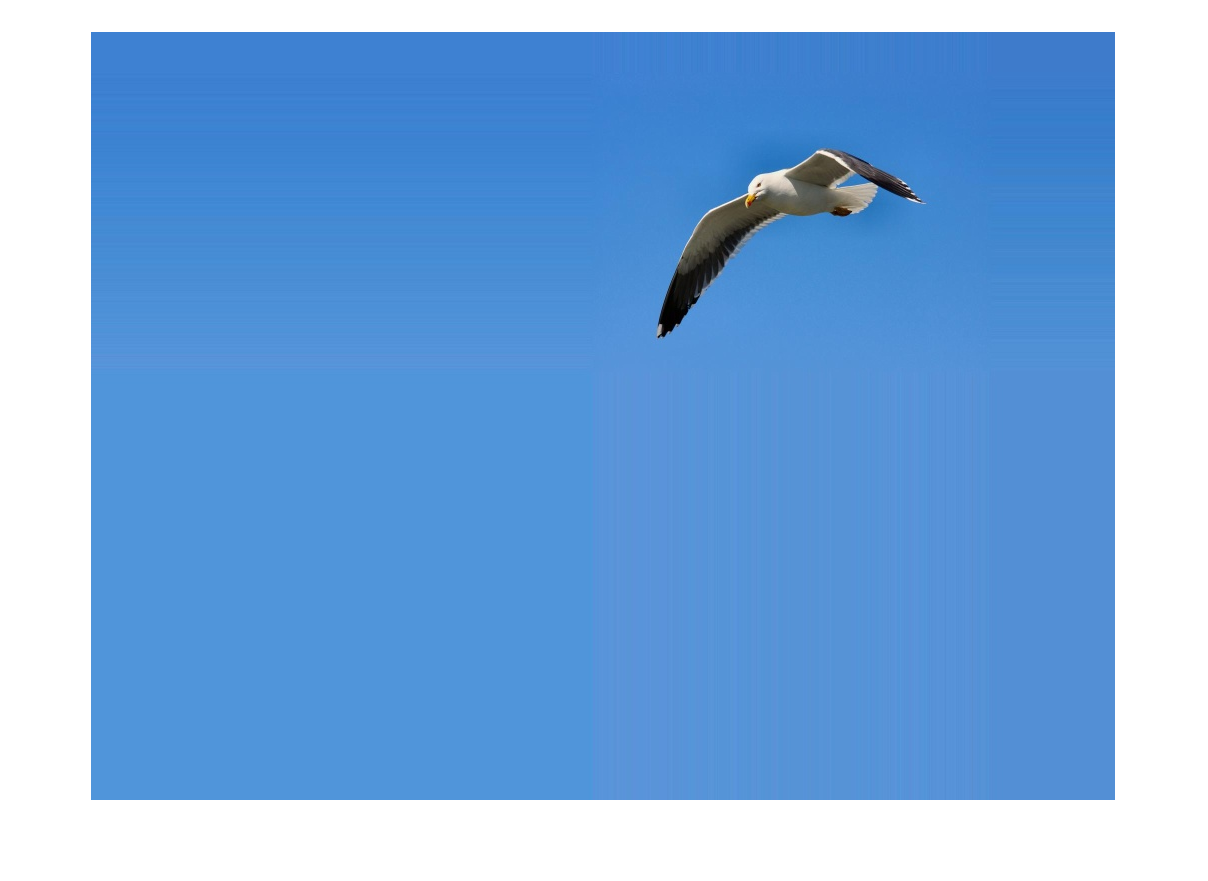

moewe=imread('moewex.jpg');
figure
imshow(moewe)

moeweSize = size(moewe)

moeweSize =          768        1024           3


Das Bild ist 768x1024 Pixeln, und hat 3 Farbenkanäle.

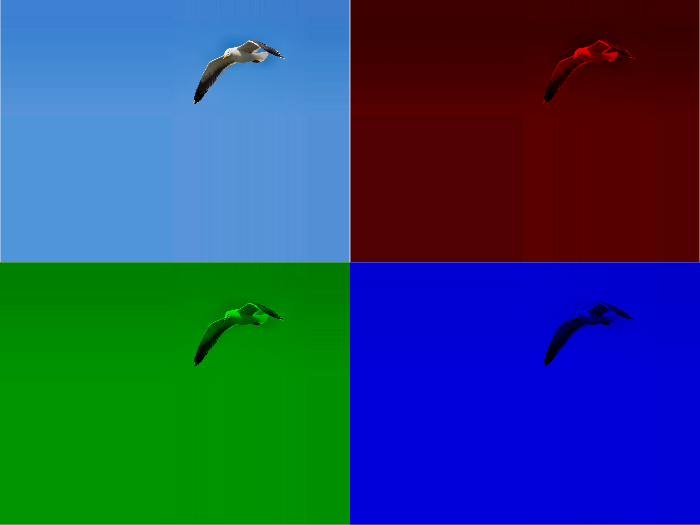

zerosMat = zeros(moeweSize(1), moeweSize(2));
showQuadView(...
    moewe,...
    cat(3, moewe(:, :, 1), zerosMat, zerosMat),...
    cat(3, zerosMat, moewe(:, :, 2), zerosMat),...
    cat(3, zerosMat, zerosMat, moewe(:, :, 3))...
)

b)

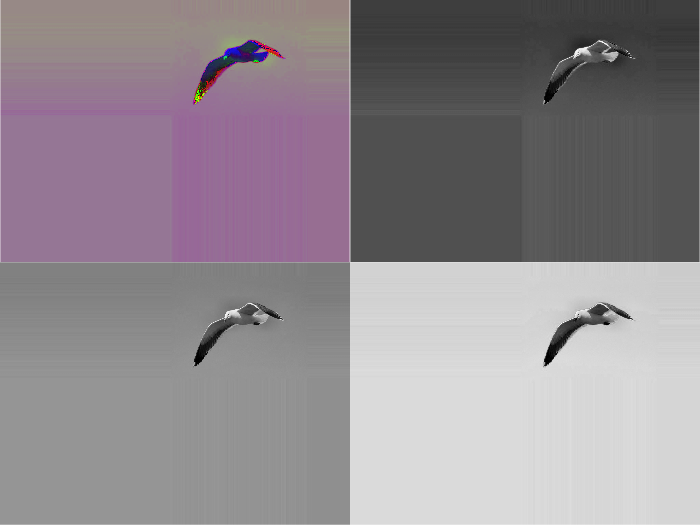

moeweHsi = rgb2hsi(moewe);
showQuadView(...
    moeweHsi,...
    moewe(:, :, 1),...
    moewe(:, :, 2),...
    moewe(:, :, 3)...
)

c/d) in HSI lässt sich die Möwe am besten vom Hintergrund unterscheiden, besonders im I (intensity) Kanal.

e) 

moeweXyz = rgb2xyz(moewe);
showQuadView(...
    moeweHsi,...
    moewe(:, :, 1),...
    moewe(:, :, 2),...
    moewe(:, :, 3)...
)

moeweLab = rgb2lab(moewe);
showQuadView(...
    moeweHsi,...
    moewe(:, :, 1),...
    moewe(:, :, 2),...
    moewe(:, :, 3)...
)

- xyz steht für CIE 1931 XYZ, lab für CIE 1976 L*a*b*.

- "ColorSpace" sagt der Funktion in welcher Farbraum das Eingabebild ist. Defaultwert ist "srgb" (wie unser Bild) also muss man den Parameter in unserem Fall nicht angeben.